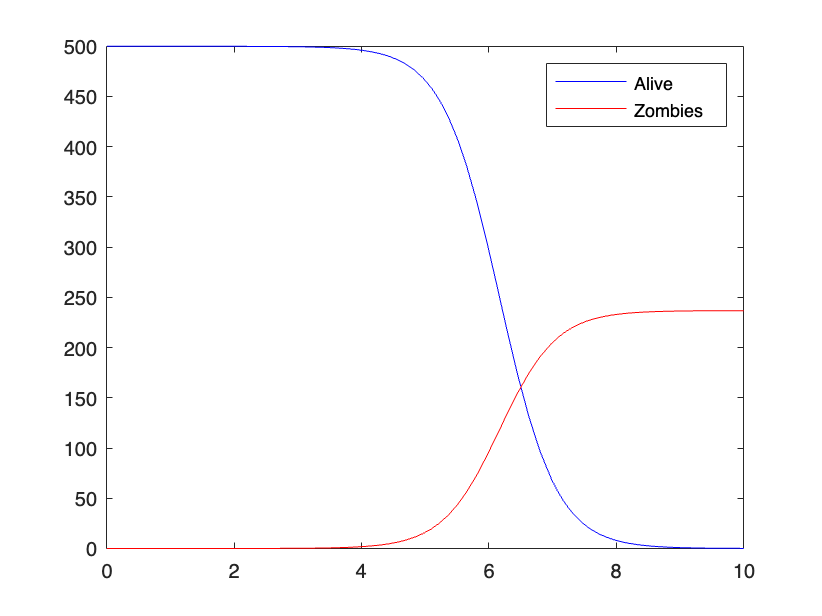

tspan = [0,10];
Y0 = [500; 0; 5];
[tSol,YSol] = ode45(@zombie,tspan,Y0);

plot(tSol,YSol(:,1),'b')
hold on
plot(tSol,YSol(:,2),'r')
hold off
legend("Alive","Zombies")

function dYdt = zombie(~,Y)
    %Setting up intitial variables
    Pi = 0;
    alpha = 0.005;
    beta = 0.0095;
    gamma = 0.0001;
    delta = 0.0001;
    
    %Setting up Dependent Variables
    S = Y(1);
    Z = Y(2);
    R = Y(3);

    %System of ODE's
    dSdt = Pi - beta*S*Z - delta*S;
    dZdt = beta*S*Z + gamma*R - alpha*S*Z;
    dRdt = delta*S + alpha*S*Z - gamma*R;

    dYdt = [dSdt ; dZdt ; dRdt];
end